clear all;

## Constants

pump_power = 1000; %[W]
pump_time = 3600*12; %[s]
pool_area = 3*8; %[m^2]

operationele_uren = 11; % [h]
nacht_uren = 24- operationele_uren;
weekend_uren = 63;

volume = pool_area*1.6;
rho = 1000;
cpw = 4186;
cp= 1005;

alpha = 5.8; %[W/m^2K] heat transfer coeff
cpa = 1005; % [kg/JK] specific heat coeff
epsilon=0.9; % white paint 
epsilon_mat = 0.9 % blue polyethylene

epsilon_mat = 0.9000

sigma= 5.67* 10^(-8) % stefan

sigma = 5.6700e-08


pump_energy = pump_power*pump_time*2.77777778 * 10^(-7); %[kWh]

## Stationair

#### Berekening damp fractie

% Ruimte
temp_ruimte = 23;
psat_ruimte = calculatePressure(temp_ruimte);
phi_ruimte = 0.65;
p=10^5;
x_ruimte = 0.622*phi_ruimte*psat_ruimte/(p-phi_ruimte*psat_ruimte)

x_ruimte = 0.0118


% Water
temp_water = 34;
psat_water = calculatePressure(temp_water);
phi_water = 1;
x_water = 0.622*phi_water*psat_water/(p-phi_water*psat_water)

x_water = 0.0362

#### Massatransport

m = alpha*pool_area/cpa*(x_water-x_ruimte) % [kg/s]

m = 0.0148

#### Warmtetransport

Latent

L = 2267000; % [J/kg] Latent heat evaporation
Q_latent = m*L

Q_latent = 3.3604e+04

Convectie

Q_convection = alpha *pool_area  *  (temp_water-temp_ruimte)

Q_convection = 6699

Straling

Q_straling = pool_area*epsilon*sigma*((temp_water+273)^4- (temp_ruimte+273)^4)

Q_straling = 6.4636e+03

Input

Q_in = Q_straling+Q_convection+Q_latent

Q_in = 4.6767e+04

#### Verbruik

verbruik_stationair = Q_in* 10^(-3) * operationele_uren % [kWh]

verbruik_stationair = 514.4336

kosten_stationair = verbruik_stationair * 0.13 * 350

kosten_stationair = 2.3407e+04

## Nacht

#### Verwarming aan 's nachts

Q_nacht_straling = pool_area*epsilon_mat*sigma*((temp_water+273)^4- (temp_ruimte+273)^4)

Q_nacht_straling = 6.4636e+03

Q_nacht_convection = alpha *pool_area  *  (temp_water-temp_ruimte)

Q_nacht_convection = 6699

Q_nacht_latent = Q_latent * 0.02

Q_nacht_latent = 672.0820

Q_nacht_out = Q_nacht_straling+Q_nacht_convection + Q_nacht_latent

Q_nacht_out = 1.3835e+04

#### Verbruik

verbruik_nacht = Q_nacht_out * 10^(-3) * nacht_uren % [kWh]

verbruik_nacht = 179.8508

#### Verwarming uit 's nachts

% Hypothetical heating added to check for lower costs
factor_weekend = 0.2;
Q_in_weekend =  factor_weekend * 1 * 10^3;
temp_ruimte = 18

temp_ruimte = 18

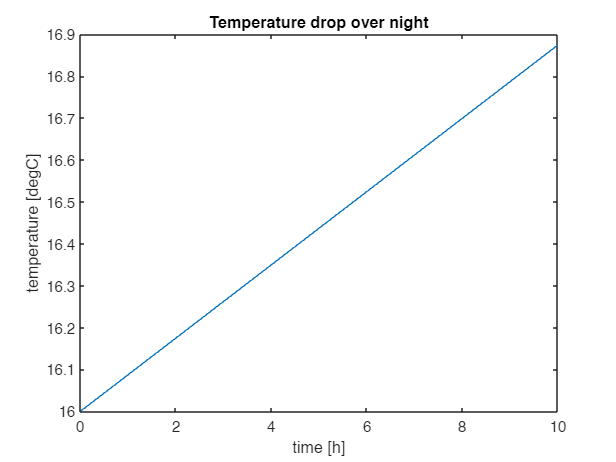

f_nacht = @(t_nacht,T_nacht) (Q_in_weekend-alpha * pool_area  *  ((T_nacht-273)-temp_ruimte) - pool_area*epsilon_mat*sigma*((T_nacht)^4- (temp_ruimte+273)^4))/(rho*volume*cpw); 
tspan_nacht = [0 (24-operationele_uren)*3600];
T0_nacht  = 34+273;
[t_nacht, T_nacht] = ode45(f_nacht,tspan_nacht,T0_nacht);
plot(t_nacht/3600, T_nacht-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Temperature drop over night')

## Weekend

tspan_weekend = [0 3600 * weekend_uren];
T0_weekend = 34+273;
[t_weekend,T_weekend] = ode45(f_nacht, tspan_weekend, T0_weekend);

Q_vector = alpha * pool_area  *  ((T_weekend-273)-temp_ruimte) + pool_area*epsilon_mat*sigma*((T_weekend).^4- (temp_ruimte+273)^4);
verloren_energie_weekend = sum(Q_vector*10^(-3)*(t_weekend(2)-t_weekend(1))/3600) %[kWh]

verloren_energie_weekend = 1.4420e+03

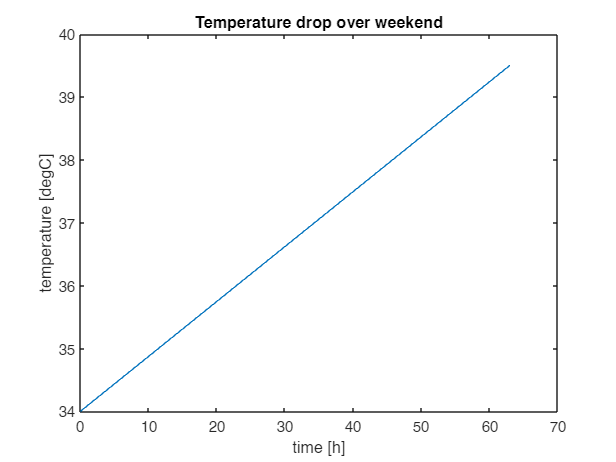

plot(t_weekend/3600, T_weekend-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Temperature drop over weekend')

## Opstart

Q_opstart_in = 75*10^3;

temp_ruimte = 22

temp_ruimte = 22

f_opstart = @(t_opstart,T_opstart) (Q_opstart_in - alpha * pool_area  *  ((T_opstart-273)-temp_ruimte) - pool_area*epsilon_mat*sigma*((T_opstart)^4- (temp_ruimte+273)^4))/(rho*volume*cpw); 
tspan_opstart = [0 3600 * 3];
T0_opstart = T_weekend(end);
[t_opstart,T_opstart] = ode45(f_opstart, tspan_opstart, T0_opstart);

idx = interp1(T_opstart, 1:length(T_opstart), 34+273, 'nearest')

idx = NaN

t_opstart(idx)/3600

Array indices must be positive integers or logical values.


kost_opstart = Q_opstart_in  *10^(-3) * t_opstart(idx)/3600 *0.13
totaal_kost_opstart = kost_opstart + weekend_uren*Q_in_weekend*10^(-3)*0.13
kost_opstart_alternatief = Q_nacht_out * 10^(-3) * weekend_uren * 0.13
plot(t_opstart/3600, T_opstart-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Heating up')